clc; clear all;

## Initial Value Problem and Boundary Value Problem

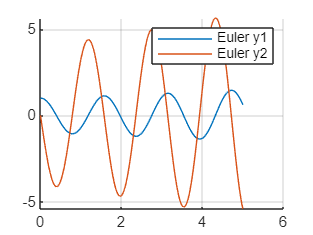

function [t, y] = explicit_euler(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    if t(end) ~= tspan(2)
        t = [t, tspan(2)]; % 벡터의 끝에 tspan(2)를 추가
    end

    y = zeros(length(y0), length(t));
    y(1:end, 1) = y0;

    for i = 1:length(t)-1
        ti = t(i);

        y(1:end, i+1) = y(1:end, i) + h * f(ti, y(1:end, i));
    end
end
m = 1; 
k = 16;
f = @(t, y) [y(2); -k/m * y(1)];

y0 = [1;0];

h = 0.01;

[eet, eey] = explicit_euler(f, [0, 5], y0, h);

figure;
hold on;
plot(eet,eey(1, 1:end));
plot(eet, eey(2, 1:end));
legend("Euler y1", "Euler y2");
grid(true);
hold off;

function [t, y] = runge_kutta4(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    if t(end) ~= tspan(2)
        t = [t, tspan(2)];
    end

    y = zeros(length(y0), length(t));
    y(1:end, 1) = y0;

    for i = 1:length(t)-1
        ti = t(i);
        k1 = f(ti, y(1:end, i));
        k2 = f(ti+0.5*h, y(1:end, i) + 0.5*k1*h);
        k3 = f(ti+0.5*h, y(1:end, i) + 0.5*k2*h);
        k4 = f(ti+h, y(1:end, i)+k3*h);
        y(1:end, i+1) = y(1:end, i) + h*(k1+2*k2+2*k3+k4)/6;
    end
end

m = 1; 
k = 16;
f = @(t, y) [y(2); -k/m * y(1)];

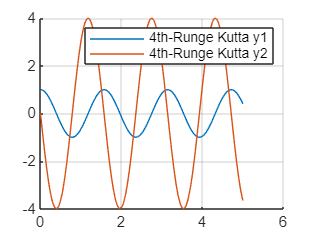


y0 = [1;0];

h = 0.05;
[r4t, r4y] = runge_kutta4(f, [0,5],y0, h);

figure;
hold on;
plot(r4t, r4y(1, 1:end));
plot(r4t, r4y(2, 1:end));
legend("4th-Runge Kutta y1", "4th-Runge Kutta y2")
grid(true)
hold off;


disp(r4y(1, 100));

    0.5815



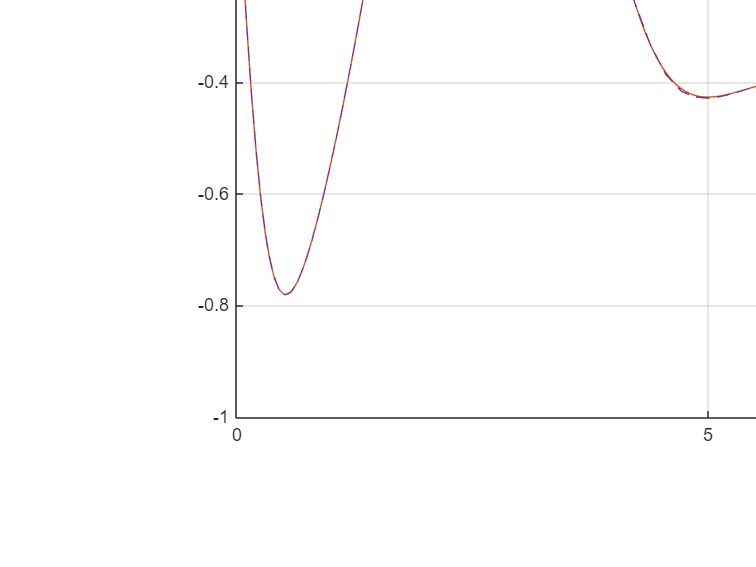

%%Problem3 
a = 5;
m = 2;
k = 6;
F0 =2.5;
w = 0.5;
y0 = [1;0];

dxdt = @(t, y) [y(2); F0*sin(w*t)- a/m*abs(y(2))*y(2)-k/m*y(1)];

[problem3_t, problem3_y] = runge_kutta4(dxdt, [0,15], y0, 0.05);

[t_sol, y_sol] = ode45(dxdt, [0,15], y0);

figure;
hold on;
plot(problem3_t, problem3_y(1, 1:end));
plot(problem3_t, problem3_y(2, 1:end));
plot(t_sol, y_sol(1:end, 1), LineStyle="--");
plot(t_sol, y_sol(1:end, 2), LineStyle="--");
legend("AutoUpdate","on")
grid("on");
hold off;

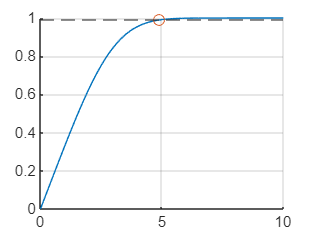

%%problem5
%fpp0는 0~0.5사이에 존재할 것이다.

function [x, f, x_position] = solve_bvp(tol)
    f0 = 0;
    fp0 = 0;
    fp10 = 1;
    h = 0.01;
    dfdx = @(t, f) [f(2); f(3); -0.5*f(1)*f(3)];
    function find_root = obj(z)
        [~, r4f] = runge_kutta4(dfdx, [0,10], [f0;fp0;z], h);
        find_root = r4f(2, end) - fp10;
    end
    root = fzero(@obj, 0.25);
    [x, f] = runge_kutta4(dfdx, [0,10],  [f0;fp0;root], h);
    for i = 1:length(f(2, 1:end))
        if abs(f(2,i) - 0.99) < tol 
           x_position = x(i);
           break;
        end
    end
end


[x, f, x_position] = solve_bvp(1e-6);
figure;
hold on;
plot(x, f(2,1:end));
scatter(x_position, f(2, x == x_position));
yline(0.99, LineStyle="--");
grid('on');
hold off;